# MATLAB을 활용한 AI 프로그래밍 - 충남대학교 김병관

- 한국전자파학회 2022 하계 전파교육 단기강좌 (8월 5일, 12일) 

- 문의사항: byungkwan.kim@cnu.ac.kr 

# 1. 통계 데이터를 활용한 분류 실습 

## 머신러닝 알고리즘을 편리하게 활용하는 방법 (Tree, Discrimination, Naive Bayes, KNN, SVM)

- Matlab에서 제공하는 classificationLerner 앱을 사용하여 편리하게 검증하는 방법

- Matlab에 구현된 함수를 사용하여 코드를 통해 구현한다 (https://kr.mathworks.com/help/stats/referencelist.html?type=function&category=classification)

## [ Activity 1 ] iris 데이타를 활용한 classificationLearner 앱 학습 

#### **1) 데이터 불러오기**

fishertable = readtable('fisheriris.csv');

- MATLAB 기본 제공 데이터의 경우, Workspace에 데이터가 로드 되었기 때문에

- 새 세션 - 작업 공간에서 를 이용해서 해당 변수를 불러온다.

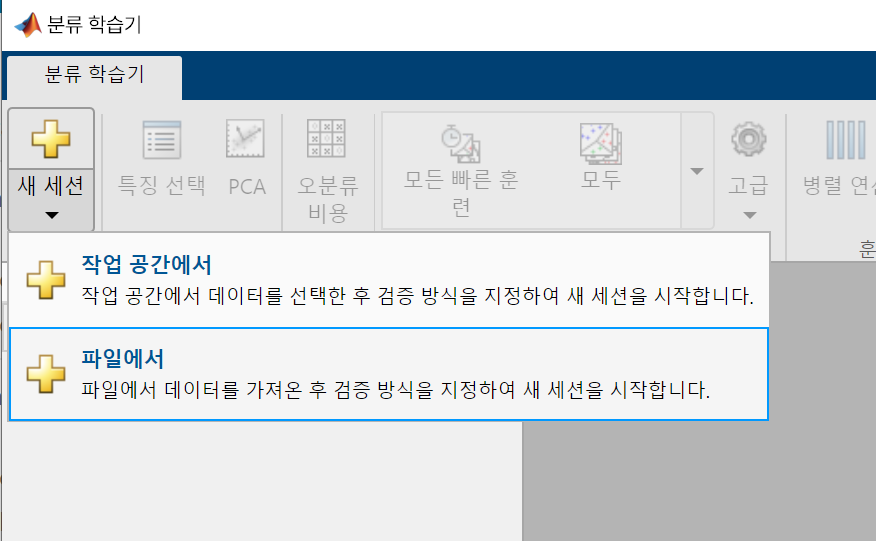

#### 2) classificationLearner 앱을 활용한 분류 실습 

아래의 명령어를 명령 창에 입력하거나, 섹션 실행을 누른다. (Ctrl + Enter)

classificationLearner

#### **3) classificationLearner 사용 방법**

- 알고리즘 선택 (일반/최적화 모델)

- 알고리즘별 하이퍼파라미터 선택  

- 훈련

- 플롯을 통한 검증

- 테스트

- 결과저장 및 Export 

#### **4) 특징 선택과 분석, PCA: 5가지 특징 분석 알고리즘을 통해 중요도가 높은 특성이 어떤 특성인지 확인 해 보세요.**

#### **5) 다양한 모델과 최적화 기법을 통해, 가장 높은 정확도를 얻어 보세요.**

## [ Activity 2 ] RF I/Q 통계 데이타를 활용한 classification 

#### 1) 활용 Dataset 소개

- Classification of Radio Signals and HF Transmission Modes with Deep Learning

- Scholl, S. (2019). Classification of radio signals and hf transmission modes with deep learning. *arXiv preprint arXiv:1906.04459*. ([https://arxiv.org/pdf/1906.04459.pdf](https://arxiv.org/pdf/1906.04459.pdf))

- 본 실습에서는 Reference Dataset의 I/Q Data (Numpy File)에서 매우 기본적인 6개의 feature를 추출하였음.

- **신호의 시간영역 feature**: mean, median, max, min, 

- **신호의 주파수영역 feature**: 최대 주파수(fft bin index), 최대 주파수의 크기 (dB scale), 두번째 주파수 및 크기

- (참고) SNR=20dB 데이터만 활용

#### 2) classificationLearner 앱을 활용한 분류 실습 

아래의 명령어를 명령 창에 입력하거나, 위의 섹션 실행을 누른다. (Ctrl + Enter)

classificationLearner

#### 3) 실습 준비 

- 새 세션 - 파일에서를 선택한다. (그림 1)

- dataset_hf_stats.csv 를 선택 후 선택항목 가져오기 

- 응답변수를 mode로 설정한다. 검증 방법의 경우 일반적으로는 교차 검증 (k-fold cross validation)이 활용된다. 

- **테스트세트 비율을 10% 설정한다.**

#### **4) 다양한 모델과 최적화 기법을 통해, 가장 높은 정확도를 얻어 보세요.**

#### **5) 검증 정확도가 가장 높은 모델이 테스트 결과에서도 높은지 확인 해 보세요. **

#### (참고) Tree 알고리즘 Visualize

- 모델 내보내기 

- 다음 명령 실행 view(trainedModel.ClassificationTree,"Mode","graph") 